# Sandsynlighed

## F2013 - Opgave 3

I denne opgave betragter vi to dartspillere, A og B. Det vides om spiller A, at hver gang, han kaster en dartpil, er der pA = 3/4 sandsynlighed for, at han rammer sit mål. Om spiller B vides, at han i 41 ud af 60 uafhængige kast har ramt sit mål.

1. Beregn sandsynligheden for, at spiller A rammer sit mål mindre end 5 gange ud af 10 uafhængige kast.

`Binomial: Sandsynligheden for at ramme k gange ud af n kast`

k = 0:4; n = 10; p = 3/4; q = 1 - p;
nk = factorial(n)./(factorial(k).*factorial(n-k));

PlayerA = sum(nk .* (p.^k .* q.^(n-k)))

PlayerA = 0.0197

Eller ved:

PlayerA = binocdf(4,n,p)

PlayerA = 0.0197

2. Beregn et estimat af sandsynligheden pB for, at spiller B rammer sit mål i et givet kast.

k = 41; n = 60;

PlayerB = k/n

PlayerB = 0.6833

## E2014 - Opgave 2

Et IT-firma modtager printede kredsløb fra to forskellige leverandører, 1 og 2. Firmaets optegnelser viser, at 5% af kredsløbene fra leverandør 1 er defekte, og 3% af kredsløbene fra leverandør 2 er defekte. 60% af firmaets nuværende beholdning af kredsløb kommer fra leverandør 1, og den resterende del af beholdningen kommer fra leverandør 2.

Lad D betegne hændelsen, at et tilfældigt udvalgt kredsløb er defekt, og lad D' være den komplementære hændelse, at kredsløbet ikke er defekt. Tilsvarende, lad S betegne hændelsen, at et tilfældigt udvalgt kredsløb kommer fra leverandør 1, og lad S' være den komplementære hændelse, at kredsløbet kommer fra leverandør 2.

`Prior: Sandsynlighed for defekt fra leverendør 1`

`Prior: Sandsynlighed for ingen defekt fra leverendør 1`

`Prior: Sandsynlighed for defekt fra leverendør 2`

`Prior: Sandsynlighed for ingen defekt fra leverendør 2`

`Prior: Sandsynlighed for levering fra leverendør 1`

`Prior: Sandsynlighed for levering fra leverendør 2`

     

PrDS = 0.05; PrNDS = 1-PrDS;
PrDNS = 0.03; PrNDNS = 1-PrDNS;
PrS = 0.6; % Leverandør 1
PrNS = 1-PrS; % Leverandør 2

1. Find sandsynlighederne Pr($S\cap D$) , Pr($S\cap \bar{D}$) , Pr($\bar{S} \cap D$) , and Pr($\bar{S} \cap \bar{D}$) .

`Joint Events: Sandsynlighed for levering fra leverendør 1 og en defekt`

PrDSS = PrDS * PrS

PrDSS = 0.0300

`Joint Events: Sandsynlighed for levering fra leverendør 1 og ingen defekt`

PrNDSS = PrNDS * PrS

PrNDSS = 0.5700

`Joint Events: Sandsynlighed for levering fra leverendør 2 og en defekt`

PrNSD = PrDNS * PrNS

PrNSD = 0.0120

`Joint Events: Sandsynlighed for levering fra leverendør 2 og ingen defekt`

PrNSND = PrNDNS * PrNS

PrNSND = 0.3880

2. Beregn den totale sandsynlighed, Pr(D) , for at et tilfældigt udvalgt kredskøb er defekt.

`Total Probality: Sandsynligheden for at en kredsløb er deffekt (Sum Rule)`

PrD = PrDS * PrS + PrDNS * PrNS

PrD = 0.0420

3. Hvis et tilfældigt udvalgt kredsløb viser sig at være defekt, hvad er så sandsynligheden for, at det kom fra leverandør 1?

`Posterior: Sandsynligheden for at et kredsløb er deffekt givet det kom fra leverandør 1 (Bayes Rule)`

PrSD = (PrDS * PrS) / PrD

PrSD = 0.7143

## E2015 - Opgave 3

format rat

Laktoseintolerans er tilstede hos 20% af den finske befolkning. Hvis en finne har laktoseintolerans, vil en test give en positiv test i 90% af tilfældene. Hvis finnen ikke har sygdommen, vil testen give en positiv test i 30% af tilfældene. 

Event A: Finne har laktoseintolerance 

Event B: Test er positiv

`Prior: Sandsynlighed for at en finne har laktoseintolerans`

`Prior: Sandsynlighed for at en finne ikke har laktoseintolerans`

       

`Likelihood: Sandsynlighed for en positiv test givet at en en finne har laktoseintolerans`

`Likelihood: Sandsynlighed for en positiv test givet at en en finne ikke har laktoseintolerans`

1) Beregn den totale sandsynlighed for at få en positiv test for en finne, hvor det er ukendt om han har laktoseintolerans. 

`Total Probality: Sandsynligheden for at en finne har en positiv test (Sum Rule)`

PrA = 0.2; PrNA = 1-PrA; PrBA = 0.9; PrBNA = 0.3; 

PrB = PrBA * PrA + PrBNA * PrNA

PrB =       21/50    


2) Hvis en finne har en positiv test, hvad er sandsynligheden for, at han også har sygdommen? 

`Posterior: Sandsynligheden for at en finne har laktoseintolereans givet en positiv test (Bayes Rule)`

PrAB = (PrBA * PrA) / PrB

PrAB =        3/7     


## F2016 - Opgave 3

format

Hændelse A er, at en gravid fødte en pige i 2012. 

Hændelse B er, at hun fødte en dreng. 

Hændelse C er, at hun fødte et barn, der vejer over 4000g. 

20,2% af alle nyfødte drenge vejede i 2012 over 4000g. 12,8% afnyfødte piger vejede i 2012 over 4000g. 

`Prior: Sandsynlighed for at en gravid fødte en pige`

`Prior: Sandsynlighed for at en gravid fødte en dreng`

`Prior: Sandsynlighed for at en gravid fødte et barn der vejede over 4000g`

1) Hvis der blev født 29.785 drenge og 28.131 piger i 2012, hvad er sandsynligheden for hændelse A? 

`Antal af Hændelse A:`

`Antal af Hændelse B:`

`Samlet antal af Hændelse A+B:`

`Likelihood: Sandsynlighed for at en gravid fødte en pige givet fødselstal (Relative Frequency Approach)`

boys = 29785; girls = 28131;

PrA = girls/(boys+girls)

PrA = 0.4857

2) Hvad er den totale sandsynlighed for hændelse C?

`Likelihood: Sandsynlighed for at en gravid fødte en dreng`

PrB = 1-PrA

PrB = 0.5143

`Total Probality: Sandsynligheden for at en gravid fødte et barn over 4000g (Sum Rule)`

PrCA = 0.128; PrCB = 0.202;

PrC = PrCA * PrA + PrCB * PrB

PrC = 0.1661

3) Hvad var sandsynligheden for at den fødende fik en pige, hvis det oplyses, at hendes barn vejede over 4000g ved fødslen?

`Posterior: Sandsynligheden for at en gravid fødte en pige givet at barnet vejede over 4000g (Bayes Rule)`

PrAC = (PrCA * PrA) / PrC

PrAC = 0.3744

## E2016 - Opgave 3

format rat

En HIV test baseret på spyt er positiv i 92% af tilfældene, givet at man er HIV smittet. Den samme test er negativ i 98% af tilfældene, givet at man er ikke er HIV smittet. Af hele befolkningen er 0,1% smittet med HIV.

Hændelse A: HIV smittet

Hændelse B: Positiv test

`Prior: Sandsynlighed for at man er HIV smittet`

`Prior: Sandsynlighed for at man ikke er HIV smittet`

       

`Likelihood: Sandsynlighed for en positiv test givet at man er HIV smittet`

`Likelihood: Sandsynlighed for en positiv test givet at man ikke er HIV smittet`

`Likelihood: Sandsynlighed for en negativ test givet at man er HIV smittet`

`Likelihood: Sandsynlighed for en negativ test givet at man ikke er HIV smittet`

PrA = 0.001; % smittet
PrNA = 1-PrA; % ikke smittet
PrBA = 0.92; % positiv givet smittet
PrNBA = 1-PrBA; % negativ givet smittet
PrNBNA = 0.98; % negativ givet ikke smittet
PrBNA = 1-PrNBNA; % positiv givet ikke smittet

1) Hvad er sandsynligheden for at en person fra befolkningen både er HIV smittet og har en positiv test?

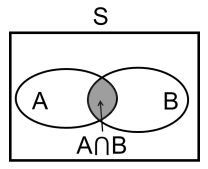

`Joint Events: Sandsynlighed for være HIV smittet og have en positiv test`

PrBAA = PrBA * PrA

PrBAA =       23/25000 


2) Hvad er den totale sandsynlighed for at en person fra befolkningen har en positiv test?

`Total Probality: Sandsynligheden for at man har en positiv test (Sum Rule)`

PrB = PrBA * PrA + PrNA * PrBNA

PrB =      111/5311  


3) Hvis en person fra befolkningen har en positiv test, hvad er sandsynligheden for, at han er HIV smittet? 

`Posterior: Sandsynligheden for at man er smittet givet en positiv test (Bayes Rule)`

PrAB = (PrBA * PrA) / PrB

PrAB =       46/1045  


4) Er begivenhederne ”At have en positv test” og ”være HIV smittet” uafhængige? begrund dit svar.

`Independence: To hændelser er uafhængige hvis følgende er gældende`

PrBAA

PrBAA =       23/25000 


Pr_AB = PrA*PrB

Pr_AB =        9/430622


De er derved ikke uafhængige.

## F2017 - Opgave 2

I juni måned (30 dage) regner det i gennemsnit 20% af dagene i den første halvdel af måneden og 30% af dagene i den sidste halvdel af måneden. 

`Prior: Sandsynlighed for regn`

`Prior: Sandsynlighed for tørvejr`

`Prior: Sandsynlighed for første/anden halvdel af måneden`

       

`Likelihood: Sandsynlighed for regn første halvdel af måneden`

`Likelihood: Sandsynlighed for regn anden halvdel af måneden`

a) Hvor mange dage regner det i gennemsnit i juni måned?

`Total Probality: Sandsynligheden for at regn i juni måned (Sum Rule)`

PrAB = 0.2; PrANB = 0.3; PrB = 0.5; 

PrA = PrAB * PrB + PrANB * PrB

PrA = 0.2500

Antal dage det regner

june = 30;
N = PrA*30

N = 7.5000

b) Hvis vi oplever en dag med regn i juni måned, hvad er så sandsynligheden for at vi er i den sidste halvdel af måneden?

`Posterior: Sandsynligheden for at det er den sidste halvdel af måneden givet at det regner (Bayes Rule)`

PrNBA = (PrANB * PrB) / PrA

PrNBA = 0.6000

c) Hvad er sandsynligheden for at det regner højst 1 dag i den første halvdel af juni?

`Binomial: Sandsynligheden for at have k dage med regn ud af n dage`

`Der kan være enten 0 eller 1 dag med regn ud af 15 dage`

k = [0 1]; n = 15; p = PrAB; q = 1 - PrAB;
nk = factorial(n)./(factorial(k).*factorial(n-k));

PrnK = sum(nk .* (p.^k .* q.^(n-k)))

PrnK = 0.1671

binocdf(1,n,p)

ans = 0.1671